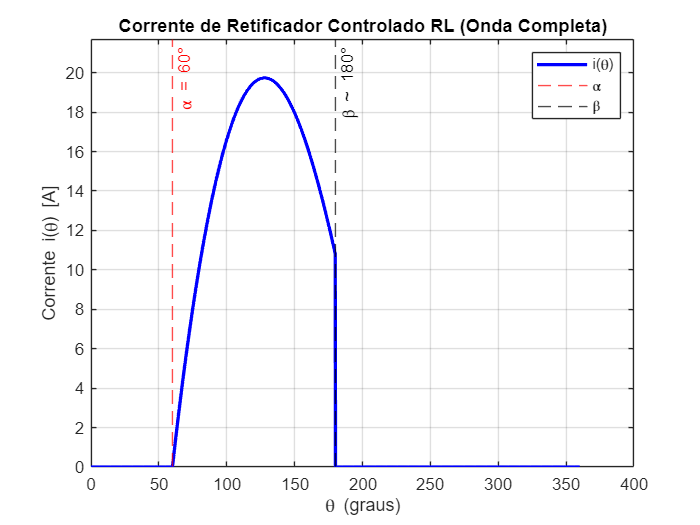

clear; clc;

% Dados
Vm = 250;      % V de pico
f  = 60;       % Hz
w  = 2*pi*f;   % rad/s
R  = 10;       % Ohms
L  = 0.0162;   % H
alpha = pi/3;  % 60 graus

% Período de 0 a 2pi
theta = linspace(0, 2*pi, 2000);

% Inicializa corrente
i_theta = zeros(size(theta));

% Calcula corrente apenas na condução (de alpha até beta)
phi = atan(w*L/R);
beta = alpha + 2*pi/3; % 120° de condução

idx = theta >= alpha & theta <= beta;
i_theta(idx) = (Vm/sqrt(R^2 + (w*L)^2)) * ...
    ( sin(theta(idx) - phi) - sin(alpha - phi) .* exp(-(R/L/w)*(theta(idx) - alpha)) );

% Plot
figure
plot(theta*180/pi, i_theta, 'b','LineWidth',2)
grid on
xlabel('\theta (graus)')
ylabel('Corrente i(\theta) [A]')
title('Corrente de Retificador Controlado RL (Onda Completa)')
xline(alpha*180/pi,'r--','\alpha = 60°')
xline(beta*180/pi,'k--','\beta ~ 180°')
ylim([0 max(i_theta)*1.1])
legend('i(\theta)','\alpha','\beta')

S